% river_base_info=readtable("river_base_info.xlsx");
% % 查找每个河段的上游河段数量
% max_upstream_count = 0;
% for index = 1:height(river_base_info)
%     downstream_id = river_base_info.HYRIV_ID(index);
%     upstream_count = sum(river_base_info.NEXT_DOWN == downstream_id);
% 
%     if upstream_count > max_upstream_count
%         max_upstream_count = upstream_count;
%     end
% end
%导入河网河段信息文件
filename='river_base_info.xlsx';
river_base_info=readtable(filename);
river_base_info=table2array(river_base_info);

%对于1层金字塔
%内外单元提取   %注意河段起点处是否有更多的n级入汇河段（多于两条河流的入汇情况）

%预分配内外单元提取的cell数组
max_unit=50000;
in_1=cell(max_unit,1);
out_1=cell(max_unit,1);

%获取河段索引的映射，减少查找时间
segment_map = containers.Map('KeyType', 'double', 'ValueType', 'any');
for i = 1:size(river_base_info, 1)
    segment_map(river_base_info(i, 1)) = i;
end

% 使用并行处理提取内单元
in_units = cell(max_unit, 1); % 中间结果
parfor i =1:size(river_base_info,1)
    if river_base_info(i,6)~=1 && river_base_info(i,8)~=1 &&...
            ~isnan(river_base_info(i,6)) && ~isnan(river_base_info(i,8))
        
        unit=[];
        hs_rank=river_base_info(i,3);
        hs_rank_next=hs_rank;
        unit(:,1)=river_base_info(i,:)';
        num=1;
        current_index=i;

        %使用segment_map快速查找
        while true
            next_segment=river_base_info(current_index,2);
            if next_segment==0
                break  %如果河段到头了退出循环
            end

            current_index=segment_map(next_segment);
            hs_rank_next=river_base_info(current_index,3);
            if hs_rank_next ~= hs_rank
                break
            end
            num=num+1;
            unit(:,num)=river_base_info(current_index,:)';
        end
        in_units{i}=unit;
    end
end

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 6 个工作进程的并行池。


% 收集有效的内单元
count_in = sum(~cellfun(@isempty, in_units));
in_1 = in_units(~cellfun(@isempty, in_units));

% 使用并行处理提取外单元
out_units = cell(max_unit, 1); % 中间结果
parfor i =1:size(river_base_info,1)
    if river_base_info(i,6)==1 && river_base_info(i,8)==1 &&...
            (river_base_info(i,10)==1 || isnan(river_base_info(i,10)))
        
        unit=[];
        hs_rank=river_base_info(i,3);
        hs_rank_next=hs_rank;
        unit(:,1)=river_base_info(i,:)';
        num=1;
        current_index=i;

        %使用segment_map快速查找
        while true
            next_segment=river_base_info(current_index,2);
            if next_segment==0
                break  %如果河段到头了退出循环
            end

            current_index=segment_map(next_segment);
            hs_rank_next=river_base_info(current_index,3);
            if hs_rank_next ~= hs_rank
                break
            end
            num=num+1;
            unit(:,num)=river_base_info(current_index,:)';
        end
        % 存储结果
        out_units{i} = unit; % 使用 i 作为下标存储
    end
end

% 收集有效的外单元
count_out = sum(~cellfun(@isempty, out_units));
out_1 = out_units(~cellfun(@isempty, out_units));

% 最后裁剪到实际大小
in_1 = in_1(1:count_in);
out_1 = out_1(1:count_out);

% %导入河网河段信息文件
% filename='river_base_info';
% river_base_info=readtable(filename);
% river_base_info=table2array(river_base_info);
% 
% %对于1层金字塔
% %内单元提取   %注意河段起点处是否有更多的n级入汇河段
% 
% %预分配内单元提取的cell数组
% in_1={};
% count=1;
% 
% %获取河段索引的映射，减少查找时间
% segment_map = containers.Map('KeyType', 'double', 'ValueType', 'any');
% for i = 1:size(river_base_info, 1)
%     segment_map(river_base_info(i, 1)) = i;
% end
% 
% for i =1:size(river_base_info,1)
%     if river_base_info(i,6)~=1 && river_base_info(i,8)~=1 && ~isnan(river_base_info(i,6)) && ~isnan(river_base_info(i,8))
% 
%         unit=[];
%         hs_rank=river_base_info(i,3);
%         hs_rank_unit=hs_rank;
%         unit(:,1)=river_base_info(i,:)';
%         num=1;
% 
%         row=find(river_base_info(:,1)==river_base_info(i,2));
%         while hs_rank_unit==hs_rank
%             num=num+1;
%             unit(:,num)=river_base_info(row,:)';
%             if river_base_info(row,2)==0
%                 break
%             end
%             row=find(river_base_info(:,1)==river_base_info(row,2));
%             hs_rank=river_base_info(row,3);
%         end
%         in_1{count}=unit;
%         count=count+1;
%     end
% end

aa=load('river_units_ratio.mat');
bb=aa.ratio_base_unit;
in_ratio_13=bb(1,3).in;
in_dis_ratio_13=in_ratio_13((in_ratio_13(:,1)==40017702),2);

in_dis_ratio_13 = in_dis_ratio_13(~isinf(in_dis_ratio_13) & ~isnan(in_dis_ratio_13)& in_dis_ratio_13 ~= 0);


Incorrect number or types of inputs or outputs for function summary.

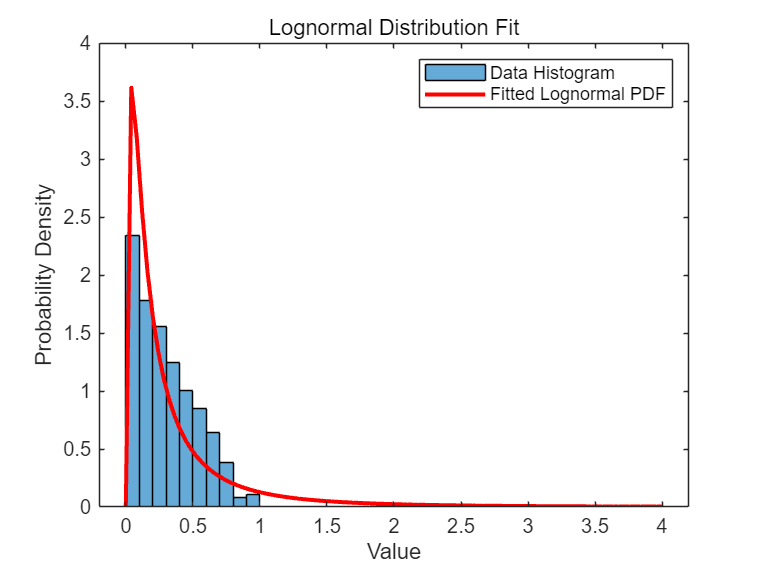

% 计算对数变换
log_data = log(in_dis_ratio_13);
% 估计对数正态分布的参数
mu = mean(log_data); % 对数均值
sigma = std(log_data); % 对数标准差

% 创建 x 值用于绘制拟合曲线
x = linspace(min(in_dis_ratio_13), max(in_dis_ratio_13), 100);
y = (1 ./ (x * sigma * sqrt(2 * pi))) .* exp(-((log(x) - mu).^2) / (2 * sigma^2));

% 绘制直方图和拟合曲线
figure;
histogram(in_dis_ratio_13, 'Normalization', 'pdf', 'BinWidth', 0.1);
hold on;
plot(x, y, 'r-', 'LineWidth', 2);
title('Lognormal Distribution Fit');
xlabel('Value');
ylabel('Probability Density');
legend('Data Histogram', 'Fitted Lognormal PDF');
hold off;